clc
clear
close all
imPath = "SortedPhotos\2Phone\"; %Folder to work with
imPathEnd = "SortedPhotos\2PhoneSC\";
OutputName = "2PhoneSC";

Prepare filepaths

imList = dir(imPath);
imPaths = repmat("",length(imList),1);
imPathsEnd = repmat("",length(imList),1);
dirs = zeros([length(imList) 1],"logical");
for i = 1:length(imList)
    dirs(i) = imList(i).isdir;
    imPaths(i) = strcat(imPath,imList(i).name);
    imPathsEnd(i) = strcat(imPathEnd,imList(i).name(1:end-3),"png");
end
imPaths(dirs) = [];
imPathsEnd(dirs) = [];
if (~exist(imPathEnd, 'dir')); mkdir(imPathEnd); end

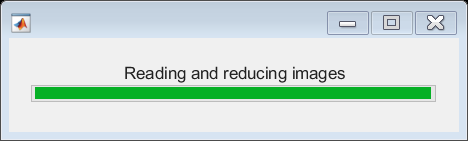

figure(1)
wb = waitbar(0,"Reading and reducing images");

sz = size(imread(imPaths(1)));
if length(sz) == 2
    sz(3) = 1;
end
sz(4) = length(imPaths);
imgRaw = zeros(sz,'uint8');
imgIn = zeros([sz(1:2)*0.25 1 sz(4)],'uint8');
for i = 1:sz(4)
    imgRaw(:,:,:,i) = imread(imPaths(i));
    
    if sz(3) == 3
        imgIn(:,:,:,i) = rgb2gray(imresize(imgRaw(:,:,:,i),0.25));
    else
        imgIn(:,:,:,i) = imresize(imgRaw(:,:,:,i),0.25);
    end
    waitbar(i/sz(4),wb)
end


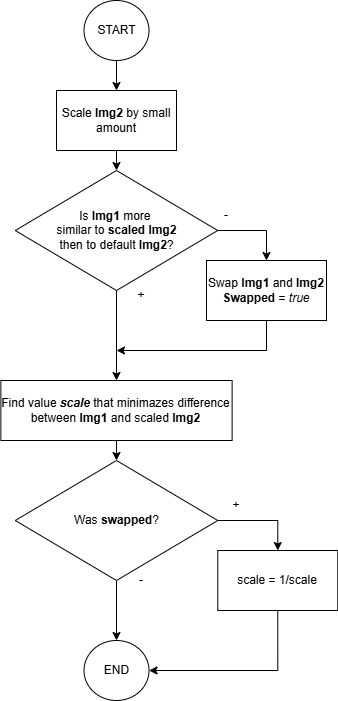

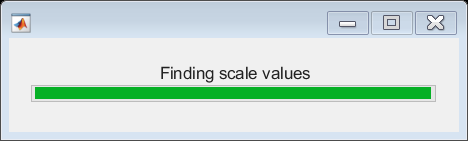

tic
smallest = 1; %index of img with scale = 1
scales = ones([sz(4) 1]); %resulting array
for i = 2:sz(4)
    waitbar(i/sz(4),wb,"Finding scale values")
    img1 = imgIn(:,:,:,smallest);
    img2 = imgIn(:,:,:,i);
    scaleSmall = 1.001; 
    swapped = false;
    diff0 = ImageDifference(img1,img2);
    img2scaled = ImageCropCentered(img2,scaleSmall);
    diff1 = ImageDifference(img1,img2scaled);
    if diff0 < diff1
        [img1, img2] = Swap(img1,img2);
        swapped = true;
        smallest = i;
    end
    
    fun = @(scale)ImageDifference(img1,ImageCropCentered(img2,scale));
    scale = fminbnd(fun,1,1.15,optimset("TolX",4e-4));
    if swapped == true
        scales = scales * scale;
        scales(i) = 1;
    else
        scales(i) = scale;
    end
end

toc

Elapsed time is 0.512949 seconds.


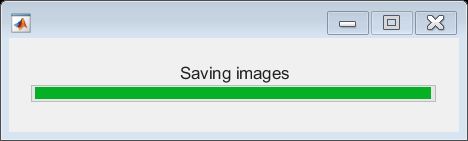

saveGIF = true;
for i = 1:sz(4)
    waitbar(i/sz(4),wb,"Saving images")
    imgOut = ImageCropCentered(imgRaw(:,:,:,i),scales(i));
    % imgOut = imgRaw(:,:,:,i);
    imwrite(imgOut,imPathsEnd(i));
    if saveGIF == true
        if i == 1
            [I,map] = rgb2ind(imresize(imgOut,0.25),256);
            imwrite(I,map,strcat(OutputName,".gif"),"gif",LoopCount=Inf,DelayTime=0.5);
        else
            I = rgb2ind(imresize(imgOut,0.25),map);
            imwrite(I,map,strcat(OutputName,".gif"),"gif",WriteMode="append",DelayTime=0.5);
        end
    end
end

close(wb)

Function definitions

function I = ImageCropCentered(I,scale)
    Iscaled = imresize(I,floor(size(I(:,:,1))*scale),"nearest");
    I = imcrop(Iscaled,centerCropWindow2d(size(Iscaled(:,:,1)),size(I(:,:,1))));
end

function score = ImageDifference(I1,I2)
    score = sum((int16(I1(:))-int16(I2(:))).^2,"all");
end

function [b,a] = Swap(a,b)
end